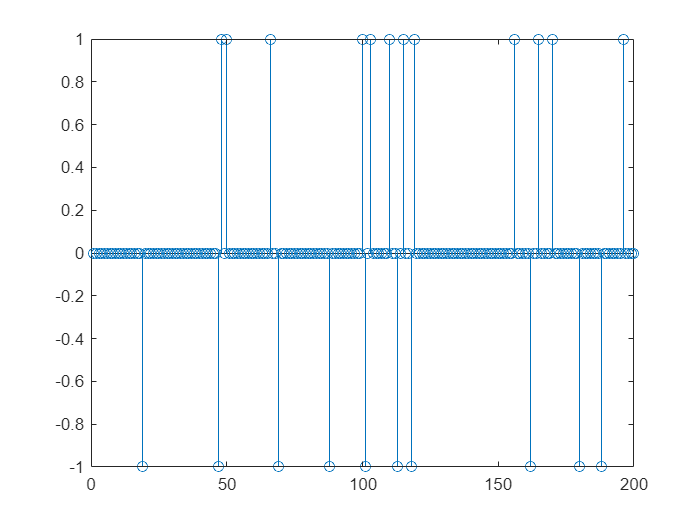

clc;clear;close all;
%a
%generating length-N Rademacher signal x
theta=0.05;
N=2000;
pop=[-1 0 1];
P_pop=[theta 1-2*theta theta];
x=randsample(pop, N, true, P_pop).';
var_x=var(x);
%plotting snippet of x
stem(x(1:200));

%b
%Generating the MxN zero mean and variance 1/M Gaussian measurement matrix
delta=0.5;
M= delta*N; %M is number of measurements
A=zeros(M,N);
for j=1:N
    A(:,j)=normrnd(0,sqrt(1/M),[M 1]);
end

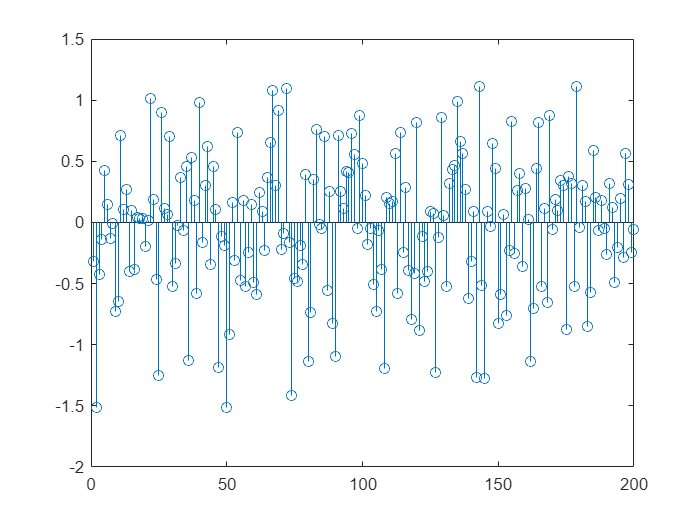

%c
%generate zero mean unit norm Gaussian noise vector
gamma=10; %SNR=10dB
z=randn([M 1]);

% pass x through the previous gaussian matrix and add noise to creat noisy
% measurements y
y=A*x+z/sqrt(gamma);
%plotting snippet of y
stem(y(1:200));


% signal parameters
epsilon = 2*theta; % probability of nonzero signal

% AMP parameters
max_iter = 20; % number of AMP iterations
lambda=0.3; % damping parameter

%d denoise function


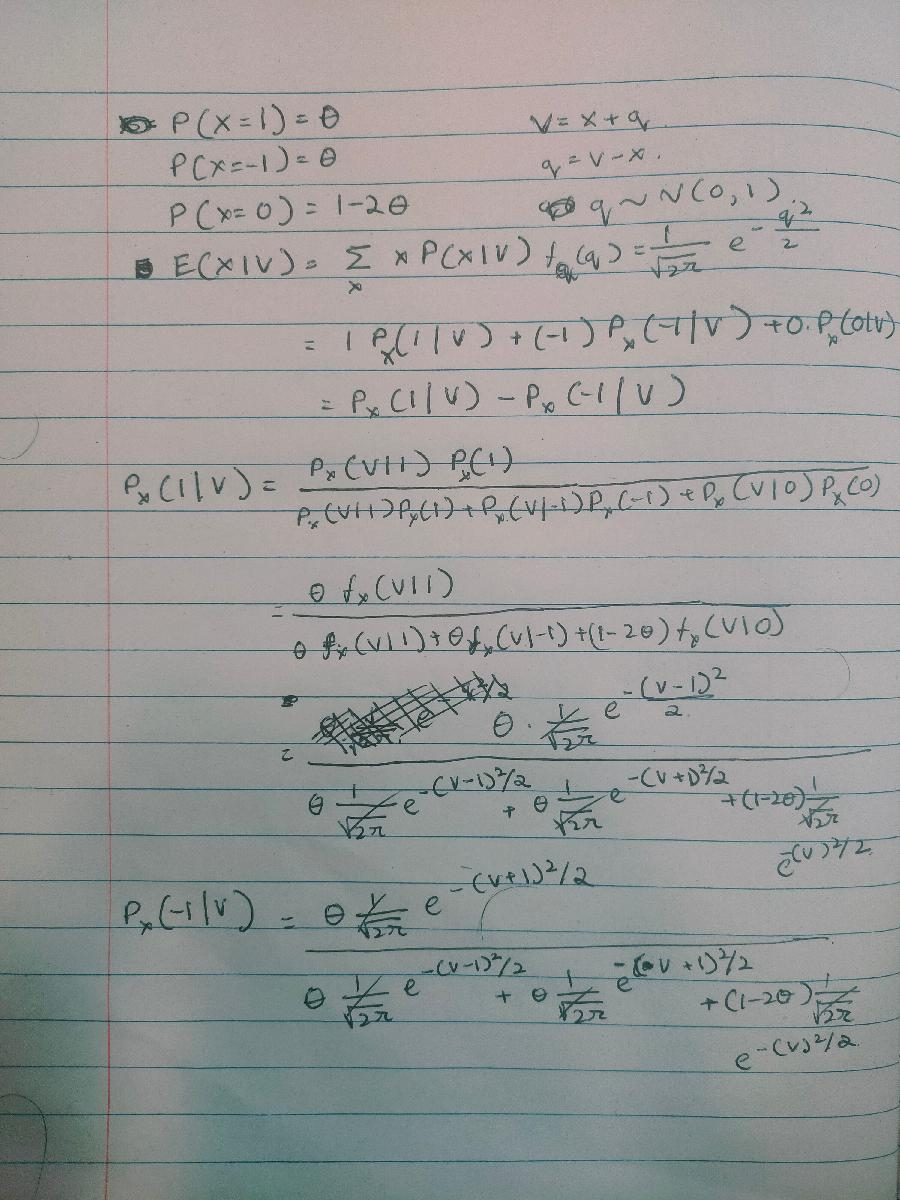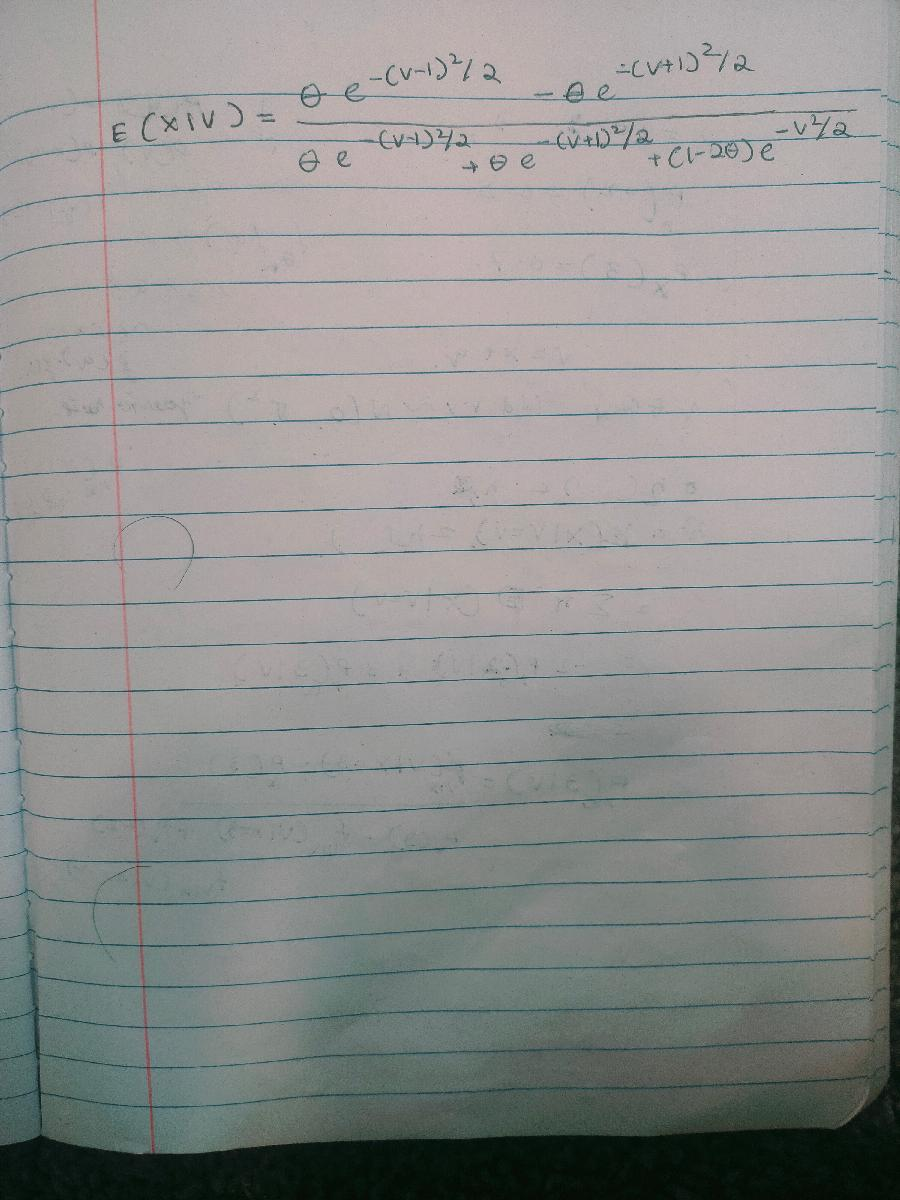


%e
%---------
% AMP algorithm
%---------
% initialization
mse = zeros(max_iter,1); % store mean square error
xt = zeros(N,1);% estimate of signal
dt = zeros(N,1);% derivative of denoiser
rt = zeros(M,1);% residual
tic;
for iter = 1:max_iter
    % update residual
    rt = y - A*xt + 1/delta*mean(dt)*rt;
    % compute pseudo-data
    vt = xt + transpose(A)*rt;
    % estimate scalar channel noise variance; estimator is due to Montanari
    var_t = mean(rt.^2);
    % denoising
    [xt1,dt] = denoise(vt,var_x,var_t,theta);
    % damping step
    xt=lambda*xt1+(1-lambda)*xt;
    mse(iter) = mean((xt-x).^2);
end
toc

Elapsed time is 0.162894 seconds.


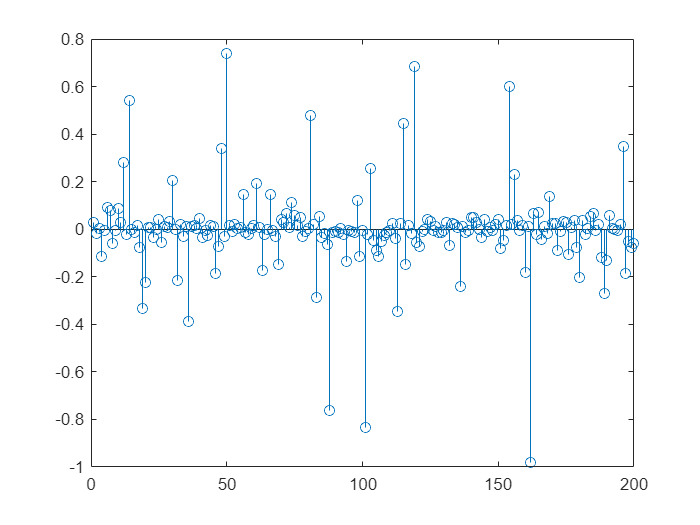

stem(xt(1:200));

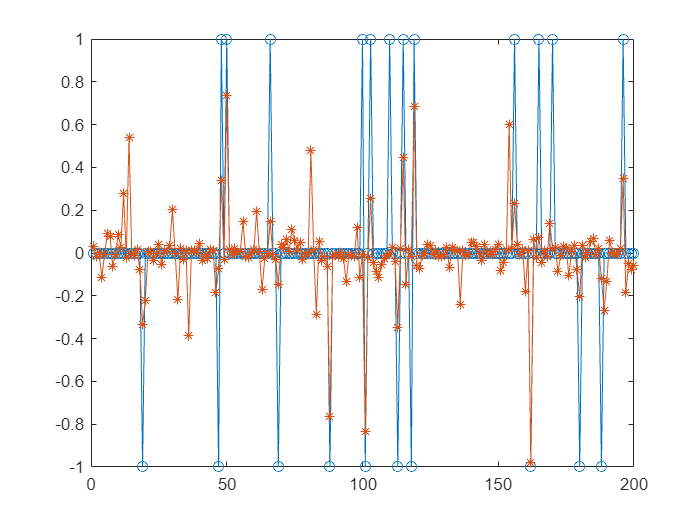

plot(1:200,x(1:200),'o-',1:200,xt(1:200),'*-');

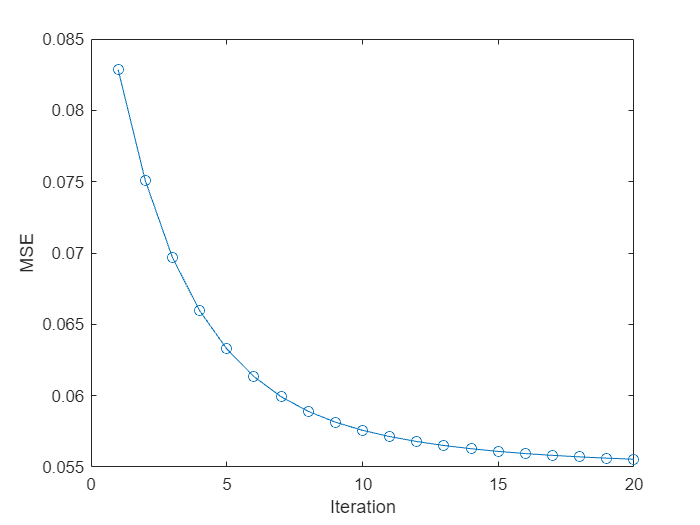

%% plot result
%figure;
plot(mse,'o-');
xlabel('Iteration')
ylabel('MSE')

fprintf('AMP error = %10.6f\n',min(mse));

AMP error =   0.055545


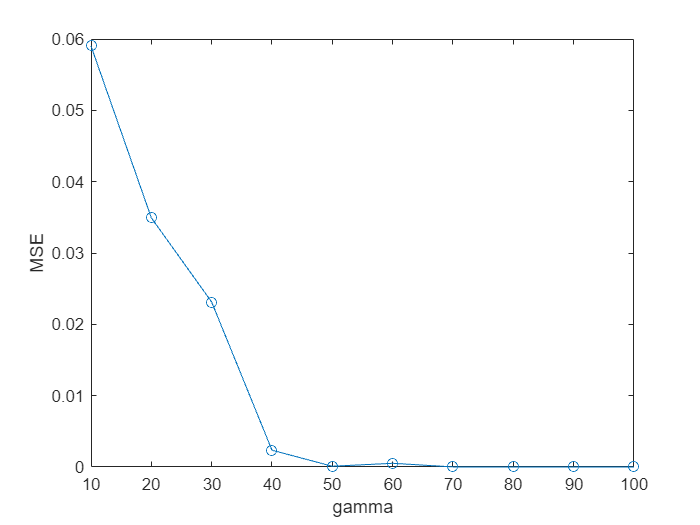

%f1

delta=0.5;
M= delta*N; %M is number of measurements
A=zeros(M,N);
for j=1:N
    A(:,j)=normrnd(0,sqrt(1/M),[M 1]);
end

gamma=10:10:100;
max_iter = 20; % number of AMP iterations
lambda=0.3;
mse = zeros(max_iter,length(gamma)); % store mean square error
for i = 1:length(gamma)
    z=randn([M 1]);
    y=A*x+z/sqrt(gamma(i));
    xt = zeros(N,1);% estimate of signal
    dt = zeros(N,1);% derivative of denoiser
    rt = zeros(M,1);% residual
    
    for iter = 1:max_iter
        % update residual
        rt = y - A*xt + 1/delta*mean(dt)*rt;
        % compute pseudo-data
        vt = xt + transpose(A)*rt;
        % estimate scalar channel noise variance; estimator is due to Montanari
        var_t = mean(rt.^2);
        % denoising
        [xt1,dt] = denoise(vt,var_x,var_t,theta);
        % damping step
        xt=lambda*xt1+(1-lambda)*xt;
        mse(iter,i) = mean((xt-x).^2);
    end
end
plot(gamma,mse(max_iter,:),'o-'); 
xlabel('gamma')
ylabel('MSE')

% MSE reduces significantly at gamma=50

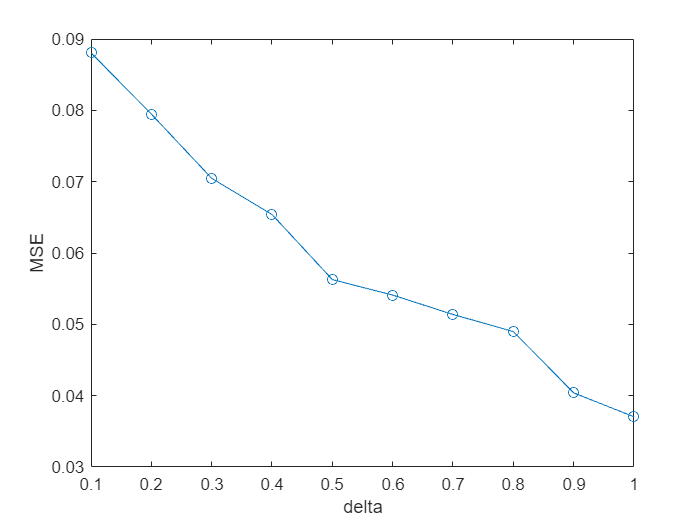

%f2
delta=linspace(0,1,11);
mse = zeros(max_iter,length(delta)); % store mean square error;

for i = 1:length(delta)
    M= delta(i)*N; %M is number of measurements
    A=zeros(M,N);
    for j=1:N
        A(:,j)=normrnd(0,sqrt(1/M),[M 1]);
    end
    
    gamma=10;
    max_iter = 20; % number of AMP iterations
    lambda=0.3;
    z=randn([M 1]);
    y=A*x+z/sqrt(gamma);
    xt = zeros(N,1);% estimate of signal
    dt = zeros(N,1);% derivative of denoiser
    rt = zeros(M,1);% residual
    for iter = 1:max_iter
        % update residual
        rt = y - A*xt + 1/delta(i)*mean(dt)*rt;
        % compute pseudo-data
        vt = xt + transpose(A)*rt;
        % estimate scalar channel noise variance; estimator is due to Montanari
        var_t = mean(rt.^2);
        % denoising
        [xt1,dt] = denoise(vt,var_x,var_t,theta);
        % damping step
        xt=lambda*xt1+(1-lambda)*xt;
        mse(iter,i) = mean((xt-x).^2);
    end
end
plot(delta,mse(max_iter,:),'o-'); 
xlabel('delta')
ylabel('MSE')

% MSE reduces with increasing values of delta=50


%---------
% linear programming
%---------
% xhat = argmin ||x||_1 s.t. y=A*x
% take x=xpos-xneg
% xpos>=0, xneg>=0
% xhat=argmin xpos+xneg s.t. y=A*(xpos-xneg)
fprintf('solving ell1\n')

solving ell1


f=ones(2*N,1);
Aeq=[A -A];
beq=y;
lb=zeros(2*N,1); % lower bound zero
ub=ones(2*N,1)*inf; % upper bound is infinity
tic;
xsolve=linprog(f,[],[],Aeq,beq,lb,ub);

Optimal solution found.



xp=xsolve(1:N);
xn=xsolve(N+1:2*N);
xell1=xp-xn;
toc

Elapsed time is 766.959616 seconds.


fprintf('ell1 error = %10.6f\n',mean((xell1-x).^2))

ell1 error = 431.451883


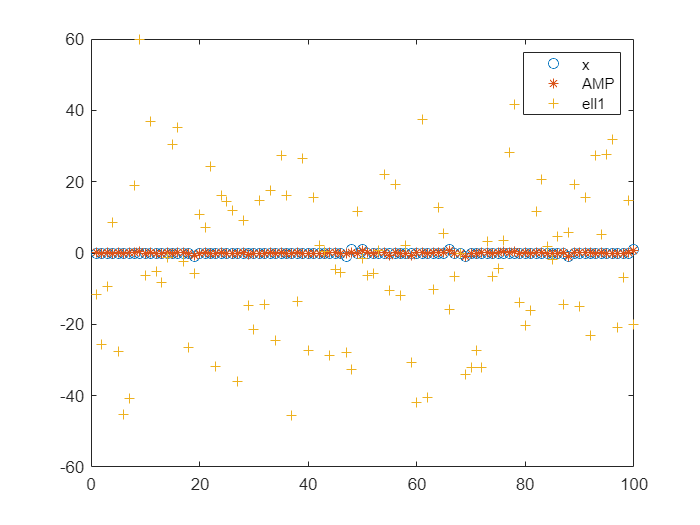


% graphics
Nplot=100;
plot(1:Nplot,x(1:Nplot),'o',1:Nplot,xt(1:Nplot),'*',1:Nplot,xell1(1:Nplot),'+')
legend('x','AMP','ell1')